clc; close all; clear all; 

data1 = readtable("Data/data_part_1.csv");
data2 = readtable("Data/data_part_2.csv");

wavelengths = data1{1,22:1742};
if not(isequal(wavelengths,data2{1,39:1759}))
    error("Wavelengths do not correspond")
end

X1= data1{2:12181,22:1742};
X2= data2{2:1116,39:1759};
X=[X1; X2];


figure;
meanSpectra=mean(X)

meanSpectra =     0.0218    0.0219    0.0220    0.0221    0.0222    0.0223    0.0224    0.0225    0.0225    0.0226    0.0227    0.0228    0.0229    0.0230    0.0231    0.0232    0.0233    0.0234    0.0234    0.0235    0.0236    0.0237    0.0238    0.0239    0.0240    0.0241    0.0242    0.0243    0.0244    0.0244    0.0245    0.0246    0.0247    0.0248    0.0249    0.0249    0.0250    0.0251    0.0252    0.0252    0.0253    0.0254    0.0254    0.0255    0.0256    0.0256    0.0257    0.0258    0.0258    0.0259


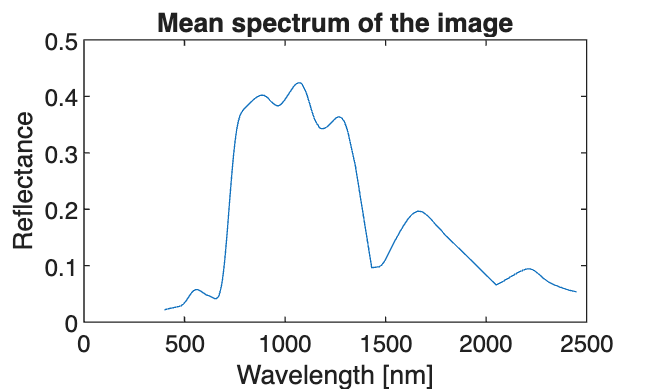

plot(wavelengths, meanSpectra);
xlabel("Wavelength [nm]");
ylabel("Reflectance");
title("Mean spectrum of the image");

%Normalize for each wavelength
[X_normalized, muX, stdX] = zscore(X);

figure;
[coeff,score,latent,tsquared,explained,mu] = pca(X_normalized);

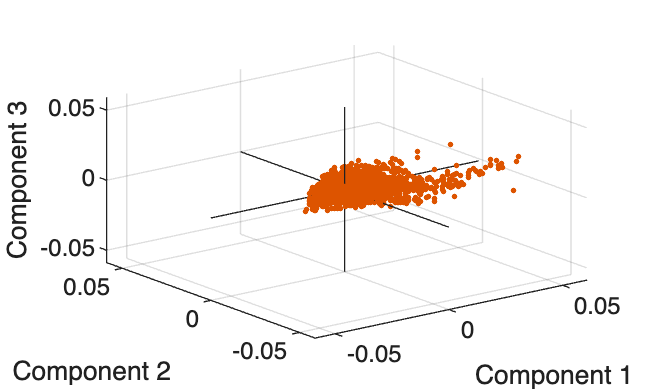


figure;
biplot(coeff(:,1:3), Scores=score(:,1:3));


var_visible= false; %set the visibility for the wavelength's contribution to the PCs
gca().Children;
varl = findobj(gca,"Tag","varline");
varl.Visible=false;
varm = findobj(gca,"Tag","varmarker");
varm.Visible=false;

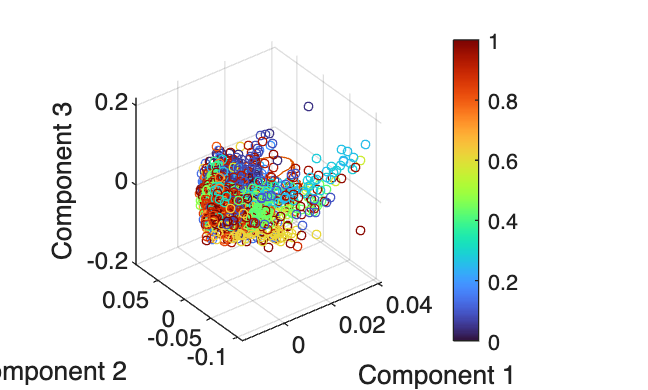

%Manual biplot

% normalize vector to go from zero to 1
normV = (score(:,4)-min(score(:,4)))./(max(score(:,4))-min(score(:,4)));


% scatter(X(:,1),X(:,2),S,C,'Marker','s')


X= score(:,1)/std(score(:,1))*std(coeff(:,1));
Y= score(:,2)/std(score(:,2))*std(coeff(:,2));
Z= score(:,3)/std(score(:,3))*std(coeff(:,3));
% Axis have to be multiplied with some unknown constant 


figure;
CC = turbo(numel(normV));
scatter3(X,Y,Z,10,CC)
hold on 
plot3(coeff(:,1),coeff(:,2),coeff(:,3))
xlabel("Component 1")
ylabel("Component 2")
zlabel("Component 3")
colormap('turbo');
colorbar
hold off

%Determine number of PCs needed with 95% of variation explained
idx = find(cumsum(explained)>95,1)

idx = 4